folder = fileparts(which('C:\Users\Sharon\OneDrive\Desktop\AnatArzi\eeglab2022.0\functions')); 
addpath(genpath(folder));

input_dir = 'C:\AnatArzData\Data\rerefrenced';
output_dir = 'C:\AnatArzData\YKM_data\epochs_and_evoked_allSubs\';
preproc_name = 'referenced';
sleep_files_name_suffix = strcat('_sleep_',preproc_name,'.set');
wake_files_name_suffix = strcat('_wake_night_',preproc_name,'.set');

subs = {'08','09','10','12','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

sleep_states_eeglab = {'N1','N2','N3','Rt','Rp'};
sleep_states = {'N1','N2','N3','REM'};
wake_states = {'Wn'};
vigilance_states_eeglab = [wake_states, sleep_states_eeglab];
vigilance_states = [wake_states, sleep_states];
TOA = {'T','O','A'};
electrodes = [5,6,11,80,85];
samples_per_epoch = 138;
toneHieghts = {'650','845','1098','1428','1856','2413','3137','4079','5302'};
trialnums = {'0','1','2','3','4','5','6','7','8','9'};
max_epochs_per_cond = 100;


% sub, vigilStage, T/O/A, hieght , trialNum, #epochs ,evokedInTime
allSubsEvokeds = zeros( size(subs,2), size(vigilance_states,2), size(TOA,2), ...
                        size(toneHieghts,2), size(trialnums,2), samples_per_epoch);

for sub_ind=1:size(subs,2)
    sub_epochs_filename = strcat(output_dir, 'epochs_sub',subs(sub_ind),'_', preproc_name, '_test.mat');
    if isfile(sub_epochs_filename)
        string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  sub_epochs_filename))
        continue
    end
    currSubEpochs =   zeros( size(vigilance_states,2), size(TOA,2), size(toneHieghts,2), ...
                            size(trialnums,2), max_epochs_per_cond, samples_per_epoch);
    
    isSleepData = 1; isWakeData = 1;
    %% get sub .set files loaded
    try
        eeglabsub_sleep =  pop_loadset(strcat('s_',subs(sub_ind),sleep_files_name_suffix), input_dir);
        subEvents_sleep = eeglabsub_sleep.event;
        subAllEpochs_sleep = eeglabsub_sleep.data;
        subAllEpochs_sleep = subAllEpochs_sleep(electrodes,:,:);
    catch ME
        isSleepData = 0;
    end
    
    try
        eeglabsub_wake =  pop_loadset( strcat('s_',subs(sub_ind),wake_files_name_suffix), input_dir);
        subEvents_wake = eeglabsub_wake.event;
        subAllEpochs_wake = eeglabsub_wake.data;
        subAllEpochs_wake = subAllEpochs_wake(electrodes,:,:); 
    catch ME
        isWakeData = 0;
    end
    
    if isSleepData + isWakeData <2
        strcat('Failed to find .set files of Sub',subs(sub_ind))
        continue
    end
    times = eeglabsub_wake.times;
    
    for vigil_ind=1:size(vigilance_states,2)
        for TOA_ind=1:size(TOA,2)
            for hieght_ind=1:size(toneHieghts,2)
                for trialnum_ind=1:size(trialnums,2)
                    
                    % get epochs numbers corresponding to a regex type of event 
                    currEventEpochsNums = [];
                    if strcmp(vigilance_states(vigil_ind),'REM')
                        currEvent_name = strcat('R[p,t]+',TOA(TOA_ind),toneHieghts(hieght_ind),'_', trialnums(trialnum_ind));
                        subEvents = subEvents_sleep;
                        subAllEpochs = subAllEpochs_sleep;
                    elseif strcmp(vigilance_states(vigil_ind),'Wn')
                        currEvent_name = strcat(TOA(TOA_ind),toneHieghts(hieght_ind),'_', trialnums(trialnum_ind));
                        subEvents = subEvents_wake;
                        subAllEpochs = subAllEpochs_wake;
                    else
                        currEvent_name = strcat(sleep_states_eeglab(vigil_ind),TOA(TOA_ind),toneHieghts(hieght_ind),'_', trialnums(trialnum_ind));
                        subEvents = subEvents_sleep;
                        subAllEpochs = subAllEpochs_sleep;
                    end
                    currEvent_name = currEvent_name{1};
                    col_type = {subEvents.type};
                    col_epochNum = {subEvents.epoch};
                    for epoch=1:size(subEvents,2)
                        if regexp(col_type{epoch},currEvent_name) == 1
                            currEventEpochsNums = [currEventEpochsNums,[col_epochNum{epoch}]];
                        end
                    end
                   
                    % get subject's event's epochs mean 
                    currEventEpochs = subAllEpochs(:,:,currEventEpochsNums); 
                    
                    % populate evoked mat
                    mean_currEventEvokeds = mean(currEventEpochs,[1,3]); % mean over trials and electrodes
                    allSubsEvokeds(sub_ind,vigil_ind,TOA_ind,hieght_ind,trialnum_ind,:) = mean_currEventEvokeds;
                    
                    % populate epochs mat
                    mean_currEventEpochs = squeeze(mean(currEventEpochs,1)); % mean over electrodes
                    if size(currEventEpochs,3) == 1
                        currSubEpochs(vigil_ind,TOA_ind,hieght_ind,trialnum_ind,1,:) = mean_currEventEpochs;
                    elseif size(currEventEpochs,3) > 1
                        currSubEpochs(vigil_ind,TOA_ind,hieght_ind,trialnum_ind,1:size(mean_currEventEpochs,2),:) = mean_currEventEpochs.';
                    end
                end
            end
        end
    end
    save(sub_epochs_filename{1}...
    ,"currSubEpochs","subs","sleep_states_eeglab","sleep_states","wake_states","vigilance_states_eeglab" ...
    ,"vigilance_states","times", "TOA","electrodes","samples_per_epoch","toneHieghts","trialnums");
end

pop_loadset(): loading file C:\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.set ...
Reading float file 'C:\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.fdt'...
Scaling components to RMS microvolt


pop_loadset(): loading file C:\AnatArzData\Data\rerefrenced\s_08_wake_night_referenced.set ...
Reading float file 'C:\AnatArzData\Data\rerefrenced\s_08_wake_night_referenced.fdt'...
Scaling components to RMS microvolt


## Look at individial trial

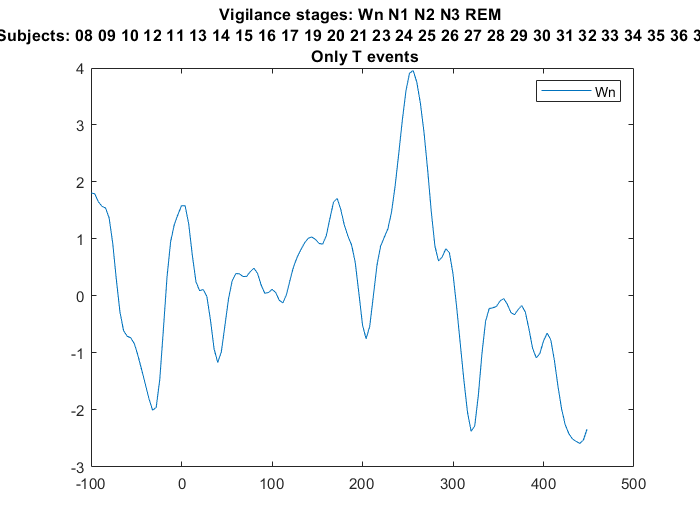

% sub, vigilStage, T/O/A, hieght , trialNum, #epochs ,evokedInTime

T_perVigiState = squeeze(allSubsEvokeds(1,1,1,1,1,:));
plot(eeglabsub_sleep.times,T_perVigiState);
title(sprintf('Vigilance stages: %s \n Subjects: %s\n Only T events', strjoin(vigilance_states),strjoin(subs)));
legend(vigilance_states);

% mkdir(strcat(output_dir,output_name))
save(string(strcat(output_dir, 'evoked_', preproc_name, '.mat'))...
    ,"allSubsEvokeds","subs","sleep_states_eeglab","sleep_states","wake_states","vigilance_states_eeglab" ...
    ,"vigilance_states","times", ...
    "TOA","electrodes","samples_per_epoch","toneHieghts","trialnums");

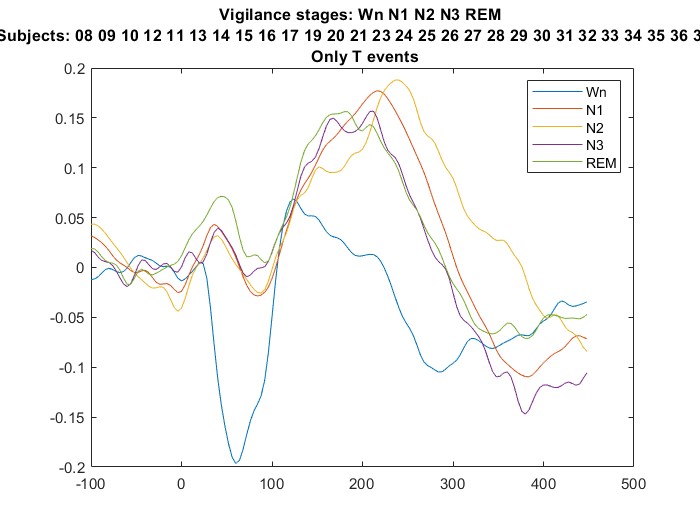

clf;
T_perVigiState = allSubsEvokeds;
T_perVigiState(:,:,[2,3],:,:,:) = [];
T_perVigiState = squeeze(T_perVigiState);
mean_T_perVigiState = squeeze(nanmean(T_perVigiState,[1,3,4]));
plot(eeglabsub_sleep.times,mean_T_perVigiState);
title(sprintf('Vigilance stages: %s \n Subjects: %s\n Only T events', strjoin(vigilance_states),strjoin(subs)));
legend(vigilance_states);

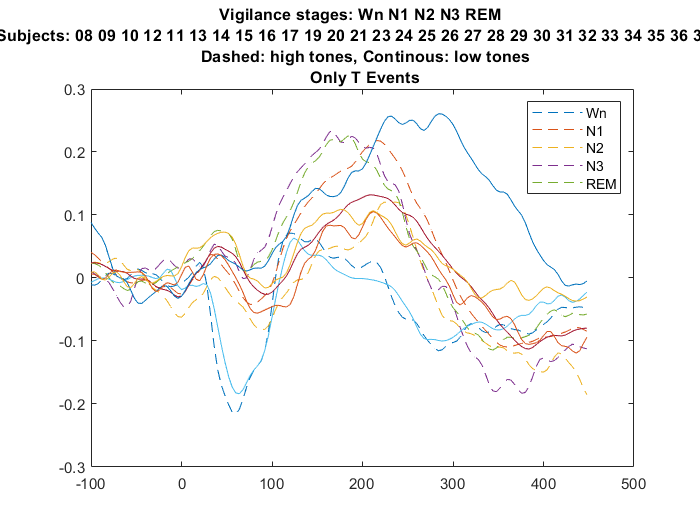

clf;
highs_perVigiState = allSubsEvokeds;
highs_perVigiState(:,:,:,1:5,:,:) = [];
highs_perVigiState(:,:,2:3,:,:,:) = [];
highs_perVigiState = squeeze(highs_perVigiState);
mean_highs_perVigiState = squeeze(nanmean(highs_perVigiState,[1,3,4]));
plot(eeglabsub_sleep.times,mean_highs_perVigiState,'LineStyle',"--");
hold on;

lows_perVigiState = allSubsEvokeds;
lows_perVigiState(:,:,:,5:9,:,:) = [];
lows_perVigiState(:,:,2:3,:,:,:) = [];
lows_perVigiState = squeeze(lows_perVigiState);
mean_lows_perVigiState = squeeze(nanmean(lows_perVigiState,[1,3,4]));
plot(eeglabsub_sleep.times,mean_lows_perVigiState);

title(sprintf('Vigilance stages: %s \n Subjects: %s\n Dashed: high tones, Continous: low tones\n Only T Events', strjoin(vigilance_states),strjoin(subs)));
legend(vigilance_states);

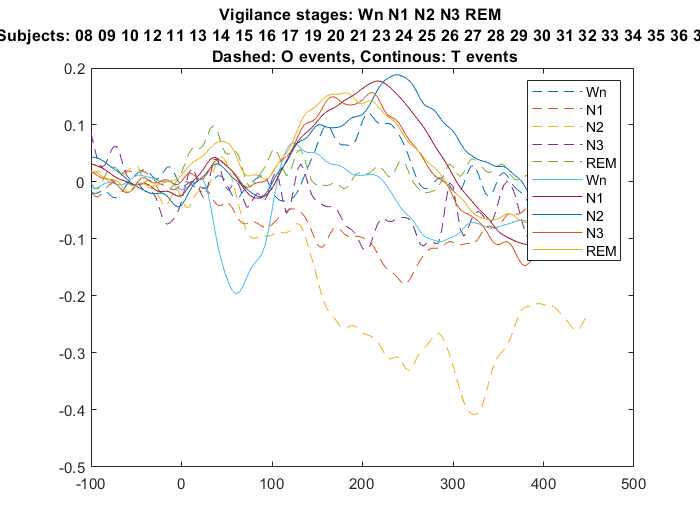

% sub, vigilStage, T/O/A, hieght , trialNum, samples
clf;
O_perVigiState = allSubsEvokeds;
O_perVigiState(:,:,[1,3],:,:,:) = [];
O_perVigiState = squeeze(O_perVigiState);
mean_O_perVigiState = squeeze(nanmean(O_perVigiState,[3,4]));  % mean over: hieght , trialNum
subStd_per_vig =  zeros(size(vigilance_states,2), samples_per_epoch);
for trial=1:samples_per_epoch
    for vigil_ind=1:size(vigilance_states,2)
        data = mean_O_perVigiState(:,vigil_ind,trial);
        sqr = sqrt(size(mean_O_perVigiState(:,vigil_ind,trial)));
        sqr = sqr(1);
        thing = std(data) / sqr;
        subStd_per_vig(vigil_ind,trial) = thing;
    end
end

mean_O_perVigiState = squeeze(nanmean(mean_O_perVigiState,1)); % mean over: subs
plot(eeglabsub_sleep.times,mean_O_perVigiState,'LineStyle',"--");
hold on;

T_perVigiState = allSubsEvokeds;
T_perVigiState(:,:,[2,3],:,:,:) = [];
T_perVigiState = squeeze(T_perVigiState);
mean_T_perVigiState = squeeze(nanmean(T_perVigiState,[1,3,4]));
plot(eeglabsub_sleep.times,mean_T_perVigiState);

title(sprintf('Vigilance stages: %s \n Subjects: %s\n Dashed: O events, Continous: T events', strjoin(vigilance_states),strjoin(subs)));
legend([vigilance_states,vigilance_states]);

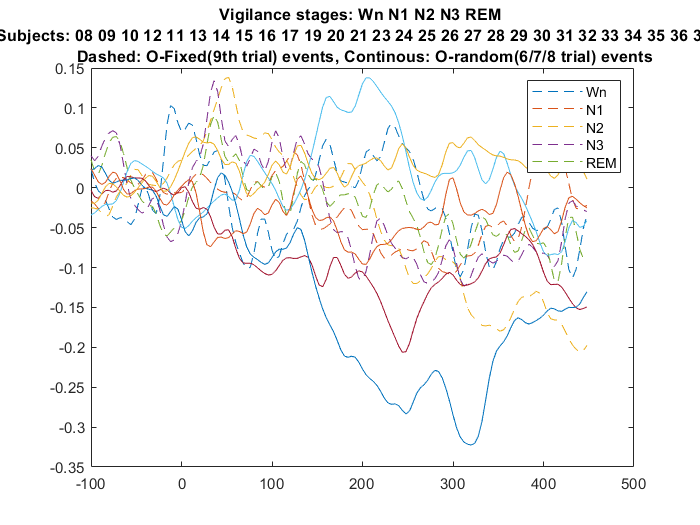

% sub, vigilStage, T/O/A, hieght , trialNum, samples
clf;
fixedO_perVigiState = allSubsEvokeds;
fixedO_perVigiState(:,:,[1,3],:,:,:) = [];
fixedO_perVigiState(:,:,:,:,1:8,:) = [];
fixedO_perVigiState = squeeze(fixedO_perVigiState);
mean_fixedO_perVigiState = squeeze(nanmean(fixedO_perVigiState,[1,3,4]));
plot(eeglabsub_sleep.times,mean_fixedO_perVigiState,'LineStyle',"--");
hold on;

randomO_perVigiState = allSubsEvokeds;
randomO_perVigiState(:,:,[1,3],:,:,:) = [];
randomO_perVigiState(:,:,:,:,[1:5,9],:) = [];
randomO_perVigiState = squeeze(randomO_perVigiState);
mean_randomO_perVigiState = squeeze(nanmean(randomO_perVigiState,[1,3,4]));
plot(eeglabsub_sleep.times,mean_randomO_perVigiState);

title(sprintf('Vigilance stages: %s \n Subjects: %s\n Dashed: O-Fixed(9th trial) events, Continous: O-random(6/7/8 trial) events', strjoin(vigilance_states),strjoin(subs)));
legend(vigilance_states);